clear;clc;close all;

Vin = 12; Vout_target = 24;
L = 1e-3; C = 100e-6; R_load = 10;
D = 0.5;

s = tf('s')';
Gvd = (Vin/(1-D)^2) * ...
    (1 - s * L / (R_load * (1-D)^2)) / ...
    (1 + s * L / (R_load * (1-D)^2) + s^2 * L * C / (1-D)^2);

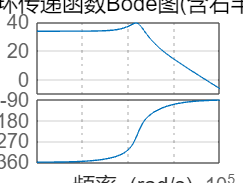

figure;
bode(Gvd);
grid on;
title('Boost开环传递函数Bode图(含右半平面零点)');